### Versió prova per defecte

% myTracker,  codi inicial del short project

close all

% Llegim el fitxer d'anotacions groundtruth_rect.txt: frame, bounding boxes, is_lost
BB = importdata('./shortProject/Boxing1/Boxing1/groundtruth_rect.txt');
Idir = dir('./shortProject/Boxing1/Boxing1/img/*.jpg');
figure
hold on % mantenim sempre oberta la mateixa figura

% filtre de Kalman
initialStateP = [BB(1,2) 0 BB(1,3) 0]; % posicio inicial i velocitat
initialStateW = [BB(1,4) 0 BB(1,5) 0]; % mida inicial i velocitat
KFP = trackingKF('MotionModel','2D Constant Velocity','State',initialStateP);
KFW = trackingKF('MotionModel','2D Constant Velocity','State',initialStateW);

nf = size(Idir); % nombre total de fitxers imatges
for i = 1:nf
    filename = horzcat(Idir(i).folder,'/',Idir(i).name);
    I = imread(filename);
    
    predP = predict(KFP); % predictor de la posicio de la finestra per Kalman
   
    correct(KFP,BB(i,2:3)); % indiquem la nova posicio detectada
    
     predW = BB(i,4:5);


    %calculem el –overlap, intersection over union-- de les finestres 
    overlapRatio = bboxOverlapRatio([predP(1),predP(3),predW(1),predW(2)],BB(i,2:5));

    % mostrem els resultats sobre la imatge
    imshow(I) % mostra el frame 
    % mostrem els rectangles:  correcte (en groc) i el predit (en vermell)
    rectangle('Position',[predP(1),predP(3),predW(1),predW(2)],'EdgeColor','red');
    rectangle('Position',BB(i,2:5),'EdgeColor','yellow');
    drawnow
end
% amplada i alçada KFW (ignorem), utilitzem el BB(i,4:5)


% reconeixement, prenc caracteristiques de la moto en el video ( i del que
% no es moto). Aprenc el que es una moto i tindrem una funcio de
% classificacio. Quan executem un altre cop el video detectarem la moto per
% reconeixement.
% tracking, amplada i alçada del groundtrouh, les altres mirem de
% detectarles un 40% mes lluny que l'anterior (si medeix 100 mirem 20 a
% esquerra i dreta)

### Primera versió, codi ransac 

close all
hold off

BB = importdata('./shortProject/Boxing1/Boxing1/groundtruth_rect.txt');
Idir = dir('./shortProject/Boxing1/Boxing1/img/*.jpg');

figure
hold on % mantenim sempre oberta la mateixa figura


%while hasFrame(VideoReader)
filename = horzcat(Idir(1).folder,'/',Idir(1).name);
I = imread(filename);
B1 = BB(1,2:5);
im_obj = rgb2gray(imcrop(I,B1));
imshow(im_obj)

nf = size(Idir); % nombre total de fitxers imatges
for i = 1:nf
   filename = horzcat(Idir(i).folder,'/',Idir(i).name);
    I2 = imread(filename);
    im_esc = rgb2gray(I2);
    % SIFT
    kp_obj = detectSIFTFeatures(im_obj);
    kp_esc = detectSIFTFeatures(im_esc);

    [feat_obj, kp_obj] = extractFeatures(im_obj,kp_obj);
    [feat_esc, kp_esc] = extractFeatures(im_esc,kp_esc);

    pairs = matchFeatures(feat_obj, feat_esc, 'MatchThreshold',2);

    m_kp_obj = kp_obj(pairs(:,1)); % agafem els millors punts
    m_kp_esc = kp_esc(pairs(:,2));

    % Ransac
    [T] = estimateGeometricTransform2D(m_kp_obj,m_kp_esc, "affine");

    [fo,co] = size(im_obj);
    [fe,ce] = size(im_esc);

    box = [1,1; co,1; co,fo; 1,fo; 1,1];

    nbox = transformPointsForward(T,box);
    imshow(im_esc)
    hold on
    line(nbox(:,1),nbox(:,2));
    drawnow
end

### Versio agafant l'imatge anterior

Primera versió implementada per nosaltres amb Sift i Ransac.

Comentaris:

1- Falta crear un else per quan no detecta punts predir-los.

2- Falta mirar que la box només es mogui un 20% respecte l'anterior.

3- Falta mirar el codi no entra mai al if.

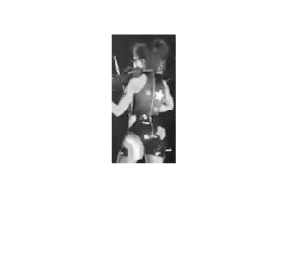

close all


BB = importdata('./ObjectTracker-main/TinyTLP/Violinist/groundtruth_rect.txt');
Idir = dir('./ObjectTracker-main/TinyTLP/Violinist/img/*.jpg');

figure
hold on % mantenim sempre oberta la mateixa figura


%while hasFrame(VideoReader)
filename = horzcat(Idir(1).folder,'/',Idir(1).name);
I = imread(filename);
B1 = BB(1,2:5);
im_obj = rgb2gray(imcrop(I,B1));
imshow(im_obj)

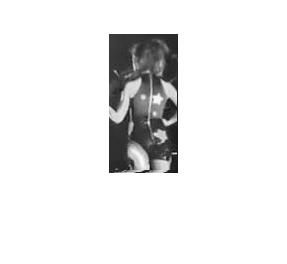


nf = size(Idir); % nombre total de fitxers imatges
for i = 1:nf
   filename = horzcat(Idir(i).folder,'/',Idir(i).name);
    I2 = imread(filename);
    im_esc = rgb2gray(I2);
    % SIFT
    kp_obj = detectSIFTFeatures(im_obj);
    kp_esc = detectSIFTFeatures(im_esc);

    [feat_obj, kp_obj] = extractFeatures(im_obj,kp_obj);
    [feat_esc, kp_esc] = extractFeatures(im_esc,kp_esc);

    pairs = matchFeatures(feat_obj, feat_esc, 'MatchThreshold',2);

    m_kp_obj = kp_obj(pairs(:,1)); % agafem els millors punts
    m_kp_esc = kp_esc(pairs(:,2));

    % Ransac
     if (m_kp_obj.Count > 3) && (m_kp_esc.Count > 3)
        [T] = estimateGeometricTransform2D(m_kp_obj,m_kp_esc, "affine");

        [fo,co] = size(im_obj);
        [fe,ce] = size(im_esc);

        box = [1,1; co,1; co,fo; 1,fo; 1,1];

        % Obtenim la capsa bona a partir de las heigh i la width
        %de la capsa original i calculant el centre de la capsa resultant 
        %de fer Sift i Ransac

        nbox = transformPointsForward(T,box);
        B1 = BB(i,2:5);
        nova_capsa = busca_centre(nbox,B1(3),B1(4));
        %imshow(im_esc)
        imshow(im_obj)
        hold on
        line(nbox(:,1),nbox(:,2));
        drawnow

    
        im_obj = rgb2gray(imcrop(I2,nova_capsa));
     end
    
end

#### Funcio més d'una imatge

videoNames = {'MotorcycleChase'; 'Boxing1'};
for i=1:size(videoNames)
    name = videoNames{i};
    kalman(name);
end


### Funcions

function [pos] = busca_centre(vector,long,up)
    p1 = vector(1,:);
    p1x = p1(1);
    p1y = p1(2);

    p2 = vector(2,:);
    p2x = p2(1);
    p2y = p2(2);
    
    p3 = vector(3,:);
    p3x = p3(1);
    p3y = p3(2);
    
    p4 = vector(4,:);
    p4x = p4(1);
    p4y = p4(2);

    centrex = mean([p1x,p2x,p3x,p4x]);
    centrey = mean([p1y,p2y,p3y,p4y]);

    % minx, miny, width, heigth
    pos(1) = centrex-long/2;
    pos(2) = centrey-up/2;
    pos(3) = long;
    pos(4) = up;

end

function [] = kalman(nom_fitxer)

    close all
    hold off

    path1 = strcat('./ObjectTracker-main/TinyTLP/', nom_fitxer);
    path11 = strcat(path1,'/groundtruth_rect.txt');
    path2 = strcat(path1,'/img/*.jpg');

    BB = importdata(path11);
    Idir = dir(path2);

    figure
    hold on % mantenim sempre oberta la mateixa figura



    filename = horzcat(Idir(1).folder,'/',Idir(1).name);
    I = imread(filename);
    B1 = BB(1,2:5);
    
    im_obje = rgb2gray(imcrop(I,B1));
    im_obj = im_obje(:,:,1);
    imshow(im_obj);


    for i = 1:50
        filename = horzcat(Idir(i).folder,'/',Idir(i).name);
        I2 = imread(filename);

        im_esce = rgb2gray(I2);
        im_esc = im_esce(:,:,1);
        % SIFT
        kp_obj = detectSIFTFeatures(im_obj);
        kp_esc = detectSIFTFeatures(im_esc);

        [feat_obj, kp_obj] = extractFeatures(im_obj,kp_obj);
        [feat_esc, kp_esc] = extractFeatures(im_esc,kp_esc);

        pairs = matchFeatures(feat_obj, feat_esc, 'MatchThreshold',2);

        m_kp_obj = kp_obj(pairs(:,1)); % agafem els millors punts
        m_kp_esc = kp_esc(pairs(:,2));

        % Ransac
        if (m_kp_obj.Count > 3) && (m_kp_esc.Count > 3)
            [T] = estimateGeometricTransform2D(m_kp_obj,m_kp_esc, "affine");
        
            Bi = BB(i,2:5);
            fo = Bi(4);
            co = Bi(3);

            box = [1,1; co,1; co,fo; 1,fo; 1,1];

            nbox = transformPointsForward(T,box);
            imshow(im_esc)
            hold on
            line(nbox(:,1),nbox(:,2));
            drawnow
        end
    end
end

Comentari: Hue no funciona, hem provat el video Hideway amb el kalman original però canviant el rgb2gray a rgb2hsv ( i agafant la component hue). No funciona ja que es perd molta informació de l'imatge: (comparar captura original, gray i hsv).